# **Matlab案例代码解析**

## 2. 典型绘图案例

### 2.3 三维绘图

#### 2.3.6 等高线图

颜值即正义；

**颜色模板参考：**[**60套优雅的颜色模板**](https://zhuanlan.zhihu.com/p/444970597)

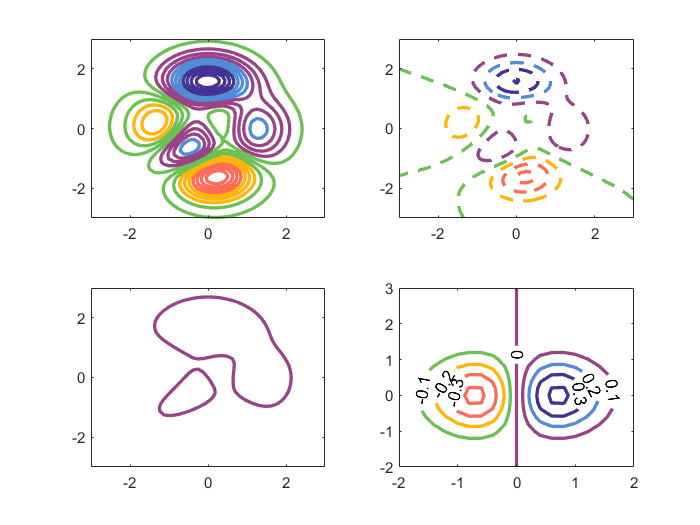

clear;clc;close all;
% 获取到颜色
[all_themes, all_colors] = GetColors(); 
figure;
[X, Y, Z] = peaks;
subplot(2, 2, 1);
contour(X, Y, Z, 20, 'LineWidth', 2);
subplot(2, 2, 2);
contour(X, Y, Z, '--', 'LineWidth', 2)
subplot(2, 2, 3);
v = [1, 1];
contour(X, Y, Z, v, 'LineWidth', 2);
x = -2:0.2:2;
y = -2:0.2:3;
[X, Y] = meshgrid(x, y);
Z = X.*exp(-X.^2-Y.^2);
subplot(2, 2, 4);
contour(X, Y, Z, 'ShowText','on', 'LineWidth', 2);
% 定制颜色
colormap(all_themes{1});

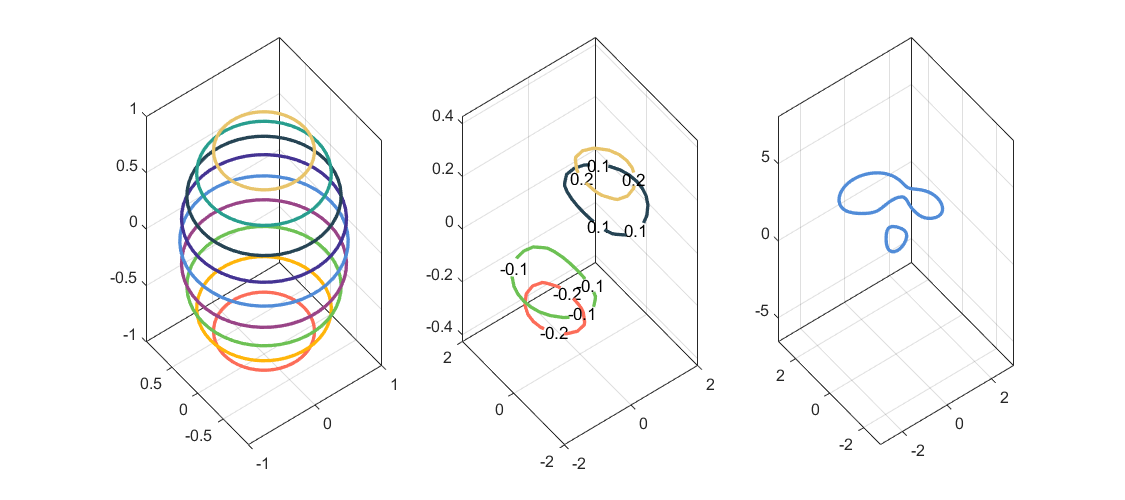

figure('Position', [0, 0, 900, 400]);
subplot(1, 3, 1);
[X, Y, Z] = sphere(50);
contour3(X, Y, Z, 'LineWidth', 2);
[X, Y] = meshgrid(-2:0.25:2);
Z = X.*exp(-X.^2-Y.^2);
subplot(1, 3, 2);
contour3(X, Y, Z, [-0.2 -0.1 0.1 0.2], 'ShowText', 'on', 'LineWidth', 2)
[X, Y, Z] = peaks;
subplot(1, 3, 3);
contour3(X, Y, Z, [2 2], 'LineWidth', 2);
% 定制颜色
colormap(all_colors(1:9, :));

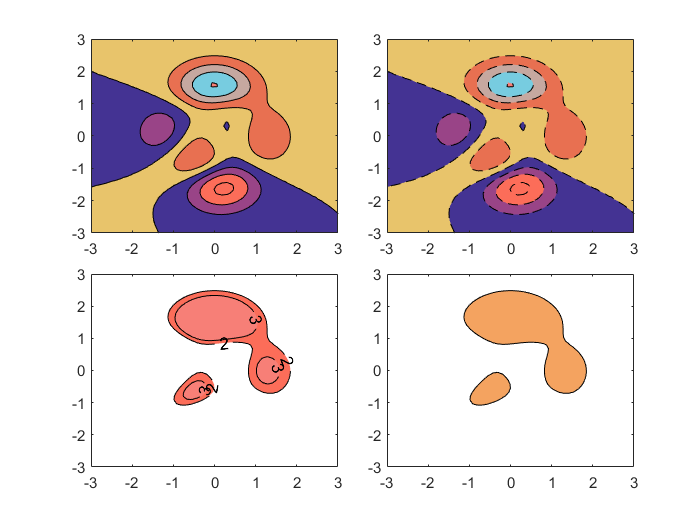

%%%%% 等高线填充图
figure;
tiledlayout(2, 2, 'TileSpacing', 'compact');
nexttile
[X, Y, Z] = peaks(50);
contourf(X, Y, Z);
nexttile
contourf(X, Y, Z,'--');
% 限定范围
nexttile
contourf(X, Y, Z, [2 3], 'ShowText', 'on');
nexttile
contourf(X, Y, Z,[2 2]);
% 定制颜色
colormap(all_colors(1:18, :));